dataDir = fullfile('./', 'Daten', 'Galaxies'); 
ellipticalDir = fullfile(dataDir, 'elliptic');
spiralDir = fullfile(dataDir, 'spiral');
irregularDir = fullfile(dataDir, 'irregular');

lbl_e(1:268) = categorical("elliptic");
lbl_e(269:268+233) = categorical("spiral");
lbl_e(268+233+1:1076) = categorical("irregular");



imds = imageDatastore(dataDir, "IncludeSubfolders", true, "Labels", lbl_e);

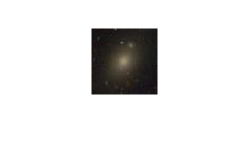

img_e = readimage(imds, 1);
imshow(img_e);

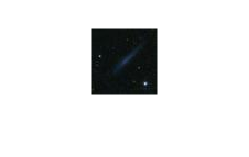

img_s = readimage(imds, 269);
imshow(img_s);

[imds_train, imds_test] = splitEachLabel(imds, 0.8);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       32.81% |       1.2012 |          0.0100 |
|       4 |          50 |       00:00:01 |       85.94% |       0.4475 |          0.0100 |
|       8 |         100 |       00:00:02 |       92.19% |       0.2883 |          0.0100 |
|      12 |         150 |       00:00:03 |       87.50% |       0.2938 |          0.0100 |
|      16 |         200 |       00:00:04 |       93.75% |       0.2187 |          0.0100 |
|      20 |         250 |       00:00:05 |       95.31% |       0.1502 |          0.0100 |
|      24 |         300 |  

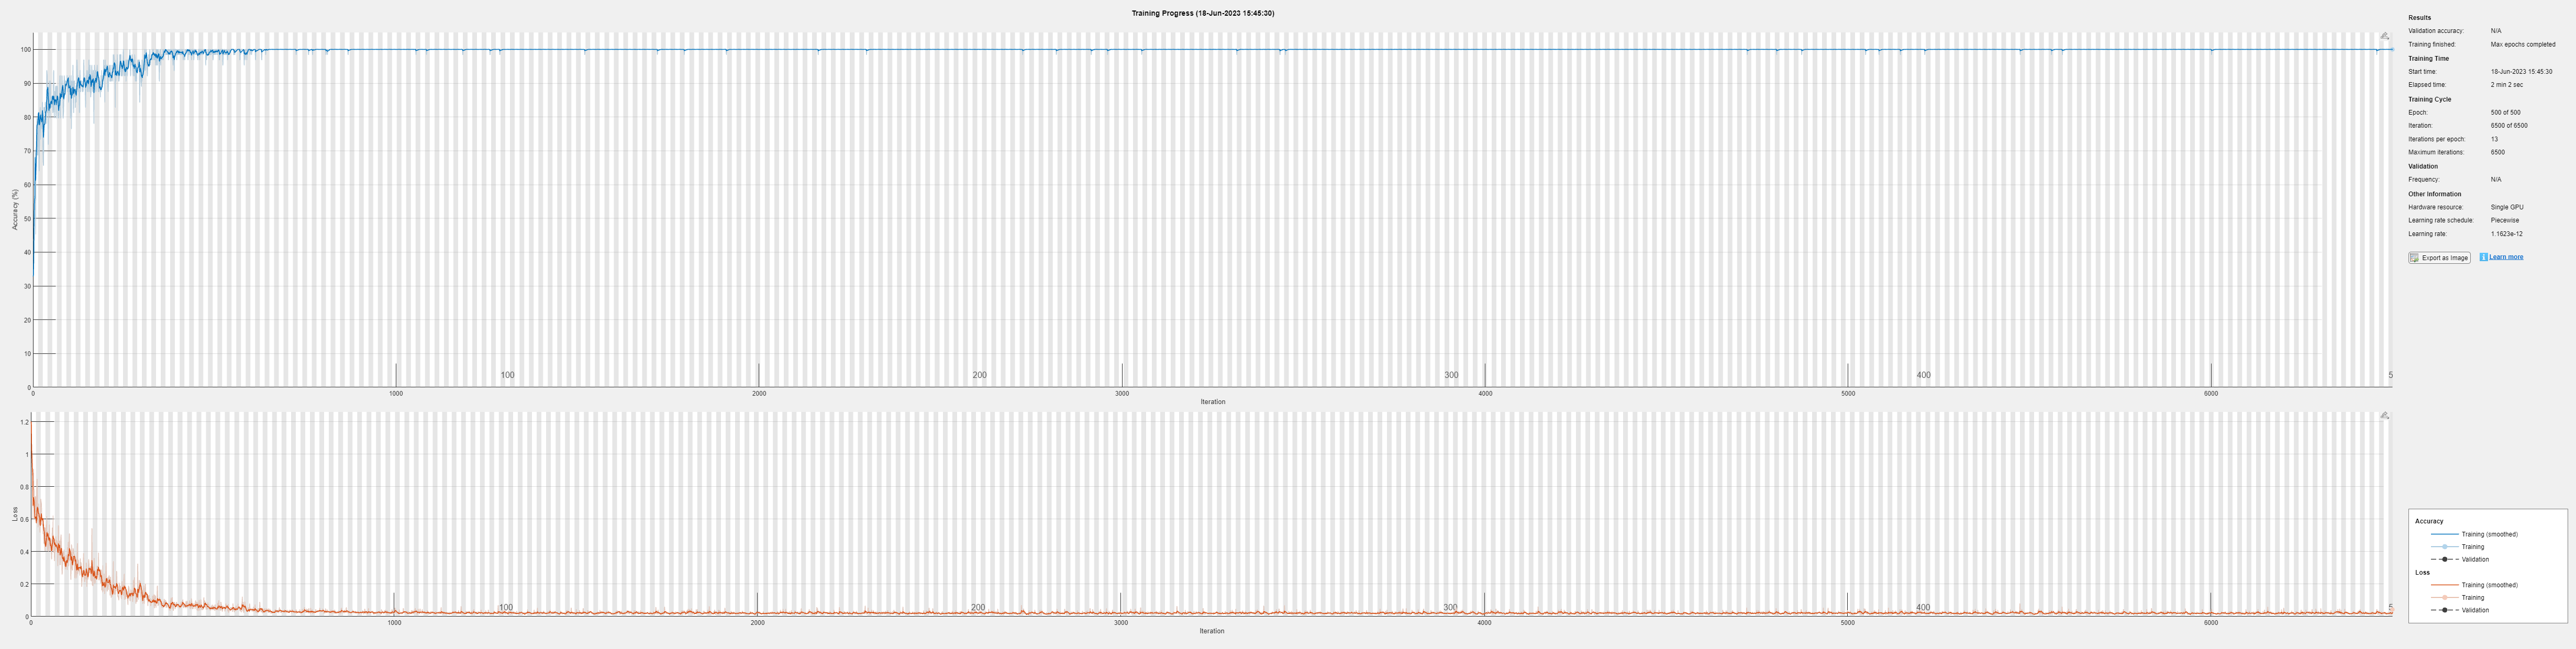

lambda = 1e-8;
layers = [
    imageInputLayer([60 60 3])
    convolution2dLayer(8, 96)
    reluLayer
    averagePooling2dLayer(3)
    fullyConnectedLayer(24)
    reluLayer
    fullyConnectedLayer(3)
    batchNormalizationLayer
    softmaxLayer
    classificationLayer
];
options = trainingOptions('adam', 'MaxEpochs', 500, 'L2Regularization', lambda, 'MiniBatchSize', 64, 'Plots', 'training-progress', 'Shuffle', 'every-epoch', 'InitialLearnRate', 0.01, 'LearnRateSchedule', 'piecewise', 'LearnRateDropPeriod', 25, 'LearnRateDropFactor', 0.3);
net_gala = trainNetwork(imds_train, layers, options);

tic
[pred, mat] = classify(net_gala, imds_test);
toc

Elapsed time is 0.187406 seconds.



testErr = sum(pred ~= imds_test.Labels) / length(imds_test.Labels);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       40.62% |       1.3226 |          0.0100 |
|       2 |          50 |       00:00:01 |       71.88% |       0.6415 |          0.0100 |
|       4 |         100 |       00:00:01 |       68.75% |       0.5869 |          0.0100 |
|       5 |         150 |       00:00:02 |       84.38% |       0.4222 |          0.0100 |
|       7 |         200 |       00:00:03 |       81.25% |       0.4176 |          0.0100 |
|       8 |         250 |       00:00:03 |       84.38% |       0.4217 |          0.0100 |
|      10 |         300 |  

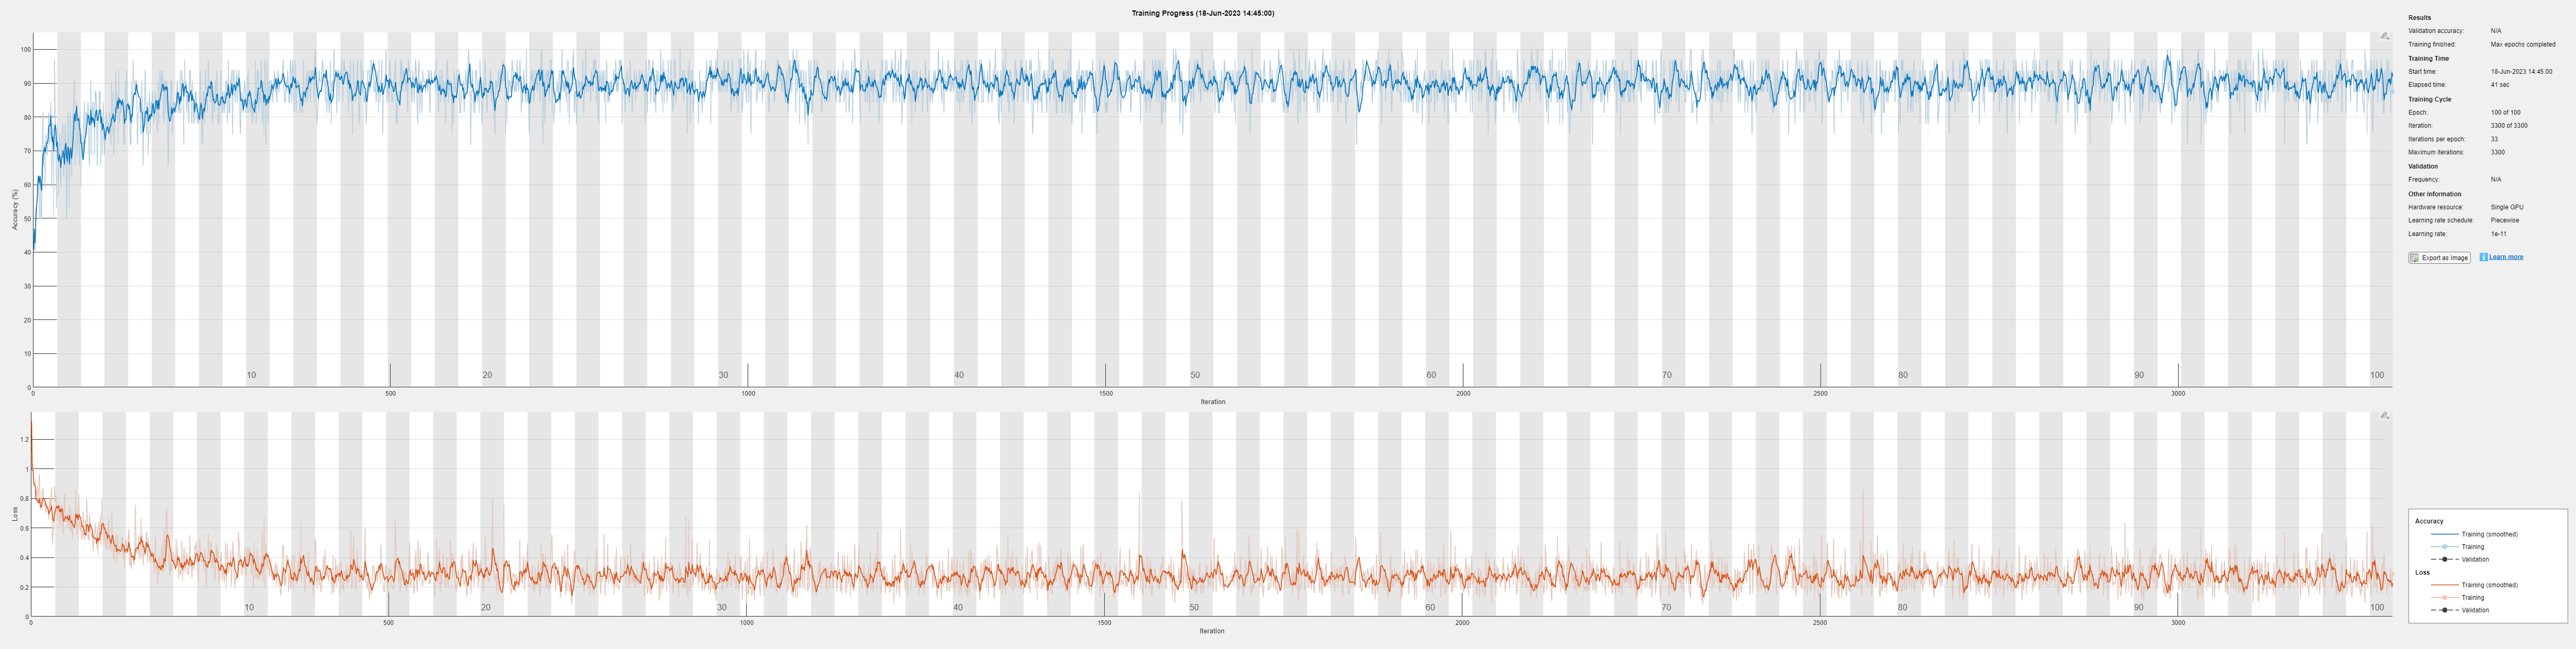

aug = imageDataAugmenter('RandRotation', [0, 120], ...
   'RandScale', [0.5, 1.2]);

augimds = augmentedImageDatastore([60 60 3], imds, 'DataAugmentation',aug);
net_gala_aug = trainNetwork(augimds, layers, options);

tic
[pred, mat] = classify(net_gala_aug, imds_test);
toc

Elapsed time is 0.194002 seconds.



testErr = sum(pred ~= imds_test.Labels) / length(imds_test.Labels);

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       43.75% |       1.2897 |          0.0100 |
|       4 |          50 |       00:00:02 |       76.56% |       0.6593 |          0.0100 |
|       7 |         100 |       00:00:03 |       68.75% |       0.6257 |          0.0100 |
|      10 |         150 |       00:00:04 |       81.25% |       0.4917 |          0.0100 |
|      13 |         200 |       00:00:05 |       87.50% |       0.3696 |          0.0100 |
|      16 |         250 |       00:00:07 |       84.38% |       0.3420 |          0.0100 |
|      19 |         300 |  

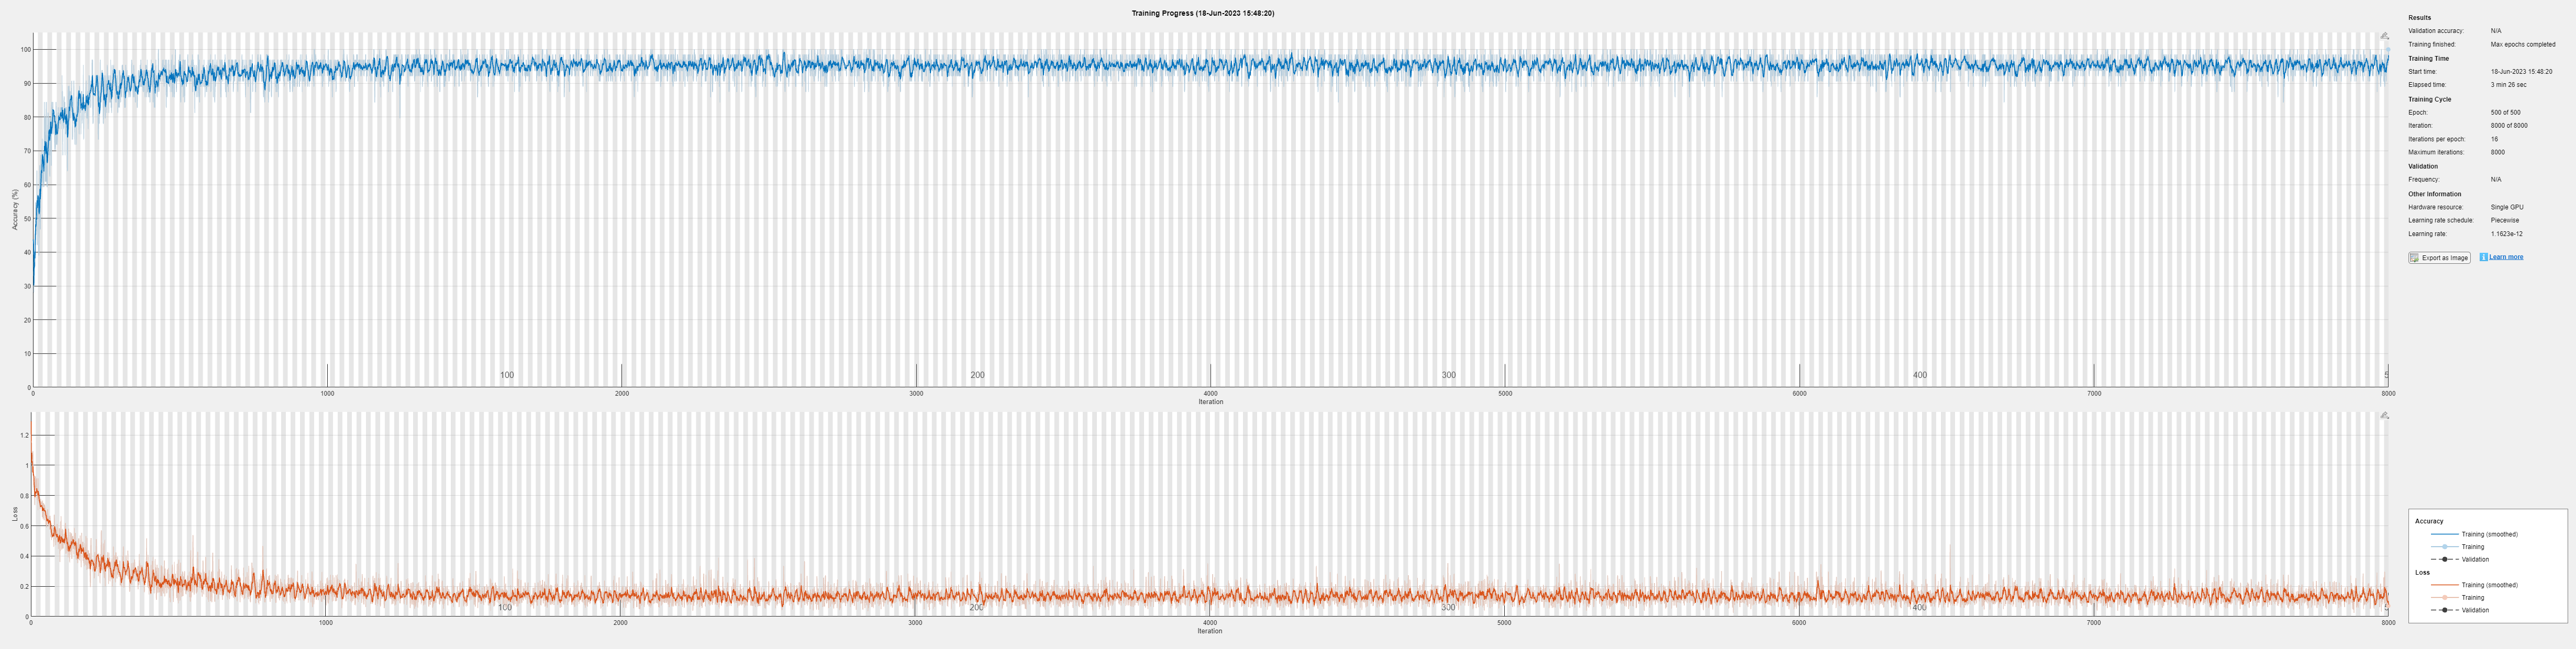

layers_custom = [
    imageInputLayer([60 60 3])
    convolution2dLayer(3, 32, "Padding", "same")
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    convolution2dLayer(3, 64, "Padding", "same")
    reluLayer
    maxPooling2dLayer(2, "Stride", 2)
    convolution2dLayer(3, 128, "Padding", "same")
    reluLayer
    maxPooling2dLayer(2, "Stride", 2)
    convolution2dLayer(3, 256, "Padding", "same")
    reluLayer
    maxPooling2dLayer(2)
    convolution2dLayer(8, 512, "Padding", "same")
    reluLayer
    fullyConnectedLayer(512)
    reluLayer
    dropoutLayer
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(3)
    batchNormalizationLayer
    softmaxLayer
    classificationLayer
];

net_gala_aug_custom = trainNetwork(augimds, layers_custom, options);

tic
[pred, mat] = classify(net_gala_aug_custom, imds_test);
toc

Elapsed time is 0.155306 seconds.



testErr = sum(pred ~= imds_test.Labels) / length(imds_test.Labels);